# Wind Support to Bird migration

**Raphaël Nussbaumer, Baptiste Schmid, Felix Liechti**

October 20th, 2020

## Abstract

[...]

- Bird airspeed has a significant influence on energy depletion and consequently on survival of migrant bird. In a context of climatique change, understanding how bird navigate in the air is essential (use of windspeed, altitude, spring vs autumn)

- In this study, we examine the airspeed chosen by bird using 30+ weather radar in Western Europe collected over a full year.

- Althgouh large variation on groundspeed were recorded, birds fly at a relative constant airspeed between season, altitude and region because the difference is due to windspeed.

## Introduction

How do bird compensate for wind?

- strengh and direction of wind

- prefered direction

- altitude

- time/season

- timing of deparute: are bird compensating more early in the night?

- (- specie of bird, size)

## Methods

**Weather radar data: bird vector speed and density**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ref) and processed as explained in Nussbaumer (2020) ([https://doi.org/10.1101/2020.10.13.321844](https://doi.org/10.1101/2020.10.13.321844)). The final dataset consisting of bird density (ρ) [bird/km^3], flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo [https://zenodo.org/record/3610185.](https://zenodo.org/record/3610185.)

load('../2018/data/dc_corr.mat','dc'); load('coastlines.mat')
NNT = datenum(repmat(dc(1).time',1,numel(dc))-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

We recompute the ground speed similarly to Nussbaumer (2020) but uses the *non-interpolated speeds* because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to the most only original data. The processing on the original data thus consists of:

- convert orientation and speed into vector (NS, EW componenents)

- removing/ignoring data when rain or scattering detected manually (similar to what was manually cleaned on the density).

- correction of groud speed by removing the difference of speed between instect and bird proportionally. (result relatively similar even when this is not done). 

- NO interpolation down to the ground, thus many datapoint missing! 

for i_d=1:numel(dc)
    
    % Compute the n/s and e/w componenent of the flight speed
    dc(i_d).u = dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0° is north and 90° is west. -> u is east (+) - west (-)
    dc(i_d).v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-)

    % Remove data not cleaned for density (e.g. rain). 
    id = isnan(dc(i_d).dens3) | dc(i_d).dens3==0;
    dc(i_d).u(id)=nan;
    dc(i_d).v(id)=nan;
   
    airspeed_u = dc(i_d).u-dc(i_d).windu;
    airspeed_v = dc(i_d).v-dc(i_d).windv;
    airspeed_l2 = sqrt((dc(i_d).u-dc(i_d).windu).^2 + (dc(i_d).v-dc(i_d).windv).^2);

    %Simple: cc = airspeed_l2 + dc(i_d).insect .* (8-2.6);
    cc = airspeed_l2.*(1-dc(i_d).insect+4.1/2.8.*dc(i_d).insect) + (8 - 2.6*4.1/2.8).*dc(i_d).insect;
    
    coef = cc./airspeed_l2;
    
    dc(i_d).u2 = airspeed_u .* coef + dc(i_d).windu;
    dc(i_d).v2 = airspeed_v .* coef + dc(i_d).windv;
end

Illustration of the insect cleaning.

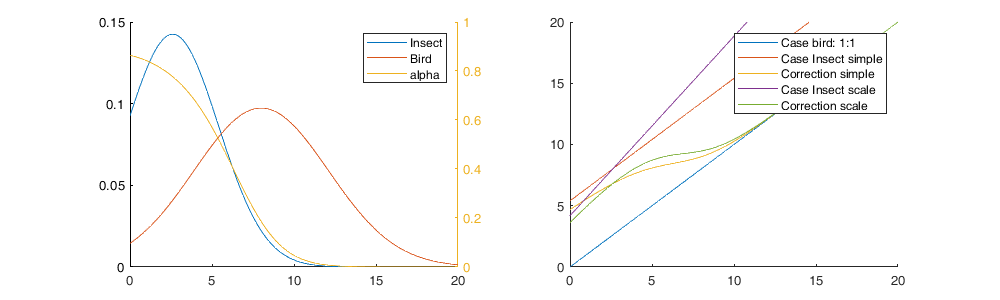

x=0:0.1:20;
pdfI = normpdf(x,2.6,2.8);
pdfB = normpdf(x,8,4.1);
alpha = pdfI./(pdfI+pdfB);
figure('position',[0 0 1000 300]); subplot(1,2,1);hold on;
plot(x,pdfI,'DisplayName','Insect');
plot(x,pdfB,'DisplayName','Bird');
yyaxis right; plot(x,alpha,'DisplayName','alpha'); legend

subplot(1,2,2); hold on;
plot(x,x,'DisplayName','Case bird: 1:1')
plot(x,x+(8-2.6),'DisplayName','Case Insect simple')
plot(x,x+(8-2.6)*alpha,'DisplayName','Correction simple')
plot(x,x.*(4.1/2.8) + 8 - 2.6.*4.1/2.8,'DisplayName','Case Insect scale');
plot(x,x.*(1-alpha+4.1/2.8*alpha) + (8 - 2.6*4.1/2.8).*alpha,'DisplayName','Correction scale');
ylim([0 20]); legend()

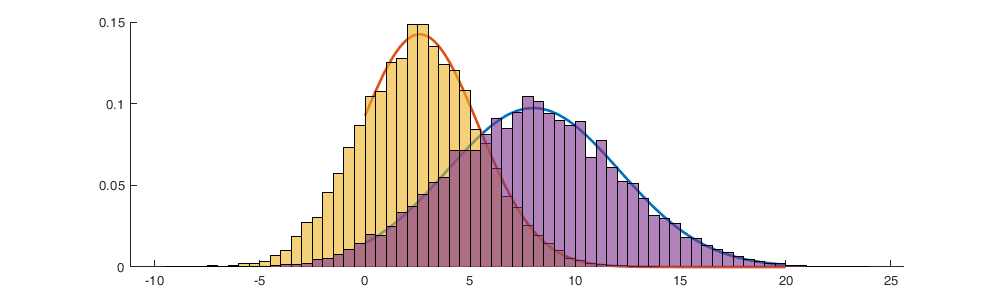

alpha =1;
X = alpha*normrnd(2.6,2.8,10000,1) + (1-alpha)*normrnd(8,4.1,10000,1);
Xcorr = X*(1-alpha+4.1/2.8*alpha) + (8 - 2.6*4.1/2.8).*alpha;
%Xcorr = X + ( -2.6 + 8 ).*alpha;
figure('position',[0 0 1000 300]); hold on;
plot(x,pdfB,'DisplayName','Bird','linewidth',2);
plot(x,pdfI,'DisplayName','Bird','linewidth',2);
histogram(X,'Normalization','pdf')
histogram(Xcorr,'Normalization','pdf')

**Climate Reanalaysis: Wind vector speed at pressure level**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind are downloaed from the ERA5 reanalysis (ref) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). Both components (`U` and `V`) are linearly interpolated (time-space 4D) at each datapoint of the weather radar data. 

**Ground and air speed**

Birds' groundspeed ($V_g$) and airspeed ($V_a$) can be computed respectively with


$$V_g =\sqrt{u^2 +v^2 }$$


and

 $V_a =\sqrt{{\left(u-U\right)}^2 +{\left(v-V\right)}^2 }$.

v_a=nan(numel(dc(1).time), numel(dc(1).alt), numel(dc)); v_g=v_a; dens = v_a; v_w =v_a; sd_vvp = v_a; dd=v_a;
for i_d=1:numel(dc)
    dd(:,:,i_d) = dc(i_d).dd;
    v_g(:,:,i_d) = sqrt(dc(i_d).u2.^2 + dc(i_d).v2.^2); % ground speed
    dc(i_d).ua=dc(i_d).u2-dc(i_d).windu; % airspeed component
    dc(i_d).va=dc(i_d).v2-dc(i_d).windv;
    v_a(:,:,i_d) = sqrt(dc(i_d).ua.^2 +dc(i_d).va.^2); % air speed
    v_w(:,:,i_d) = sqrt(dc(i_d).windu.^2 + dc(i_d).windv.^2); % wind speed
    tmp = dc(i_d).dens4;
    tmp(:,1:dc(i_d).scatter_lim)=nan;
    dens(:,:,i_d)=tmp; 
    sd_vvp(:,:,i_d) = dc(i_d).sd_vvp;
end

## Radar data availability

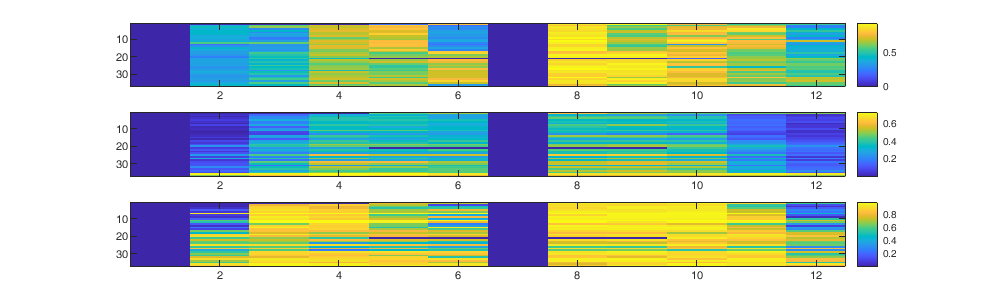

for i_m=1:12
    for i_d=1:numel(dc)
        i_t = month(dc(i_d).time')==i_m & NNT(:,i_d)>-1 & NNT(:,i_d)<1;
        nandens(i_m,i_d) = mean(any(~isnan(dens(i_t,:,i_d)),2));
        nanv_gvsens(i_m,i_d) = sum(sum(~isnan(v_g(i_t,:,i_d)))) ./ sum(sum(~isnan(dens(i_t,:,i_d))));
        nanav_gofdens(i_m,i_d) = nansum(nansum(dens(i_t,:,i_d).*~isnan(v_g(i_t,:,i_d)))) ./ nansum(nansum(dens(i_t,:,i_d)));
    end
end

figure('position',[0 0 1000 300]);
subplot(3,1,1); imagesc(nandens'); colorbar;
subplot(3,1,2); imagesc(nanv_gvsens'); colorbar;
subplot(3,1,3); imagesc(nanav_gofdens'); colorbar;

## **Seasonal Variation**

Early spring (March), Late spring (April), Early autumn (august-september) and late autumn (October).

id_sp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-May-2018');
id_esp = dc(1).time>datetime('1-Mar-2018') & dc(1).time<datetime('1-April-2018');
id_lsp = dc(1).time>datetime('1-April-2018') & dc(1).time<datetime('1-May-2018');
id_au = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Nov-2018');
id_eau = dc(1).time>datetime('1-August-2018') & dc(1).time<datetime('1-Oct-2018');
id_lau = dc(1).time>datetime('1-Oct-2018') & dc(1).time<datetime('1-Nov-2018');
id_s = [id_esp; id_lsp; id_eau; id_lau];
id_s_name = {'March','April','Aug-sept.','October'};

## Geographical separation

We define two geographical area perpendicular to the average flow orientation (`222°`), and splitting the radars in two groups of equal size. The Southern group include all Franch radar exepect `frman` (18) and the northern group include all germans (16), dutch (2) and Belgium (1) radars. See appendix .. for details. 

id_no = [true(16,1); false(12,1); true ;false(6,1) ;true(2,1)];
id_so = ~id_no;
id_de = [false; true(15,1); false(21,1)];
id_fr = [false(16,1); true(19,1); false(2,1)];

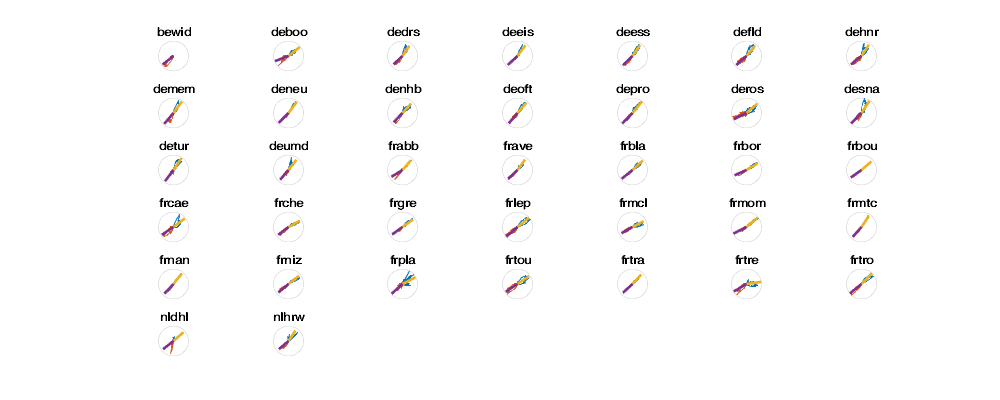

figure('position',[0 0 1000 400]);
for i_d=1:numel(dc)
    [esp,hsp,Mdd(i_d,1)] = histvdens(mod(dc(i_d).dd(id_sp,:)+(180-45),360),dens(id_sp,:,i_d));
    esp=deg2rad(esp-(180-45)); Mdd(i_d,1)=deg2rad(Mdd(i_d,1)-(180-45));
    [eau,hau,Mdd(i_d,2)] = histvdens(mod(dc(i_d).dd(id_au,:)+(180-225),360),dens(id_au,:,i_d));
    eau=deg2rad(eau-(180-225)); Mdd(i_d,2)=deg2rad(Mdd(i_d,2)-(180-225));
    
    subplot(6,7,i_d); 
    polarplot(esp,hsp);hold on
    polarplot(eau,hau);
    polarplot([Mdd(i_d,1) Mdd(i_d,1)],[0 max([hsp;hau])],'LineWidth',2)
    polarplot([Mdd(i_d,2) Mdd(i_d,2)],[0 max([hsp;hau])],'LineWidth',2)
    Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];
    title(dc(i_d).name)
end

Mean direction of flow in Spring and Autumn:

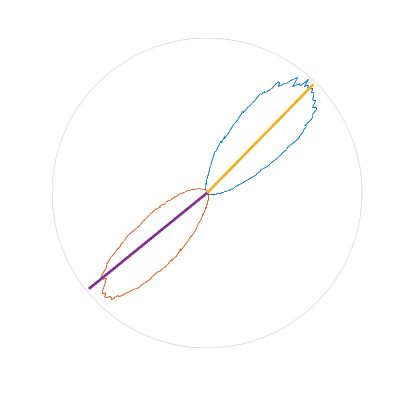

[esp,hsp,Mddm(1)] = histvdens(mod(dd(id_sp,:,:)+(180-45),360),dens(id_sp,:,:));
esp=deg2rad(esp-(180-45)); Mddm(1)=deg2rad(Mddm(1)-(180-45));
[eau,hau,Mddm(2)] = histvdens(mod(dd(id_au,:,:)+(180-225),360),dens(id_au,:,:));
eau=deg2rad(eau-(180-225)); Mddm(2)=deg2rad(Mddm(2)-(180-225));

figure('position',[0 0 400 400]);
polarplot(esp,hsp);hold on
polarplot(eau,hau);
polarplot([Mddm(1) Mddm(1)],[0 max([hsp;hau])],'LineWidth',2)
polarplot([Mddm(2) Mddm(2)],[0 max([hsp;hau])],'LineWidth',2)
Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];

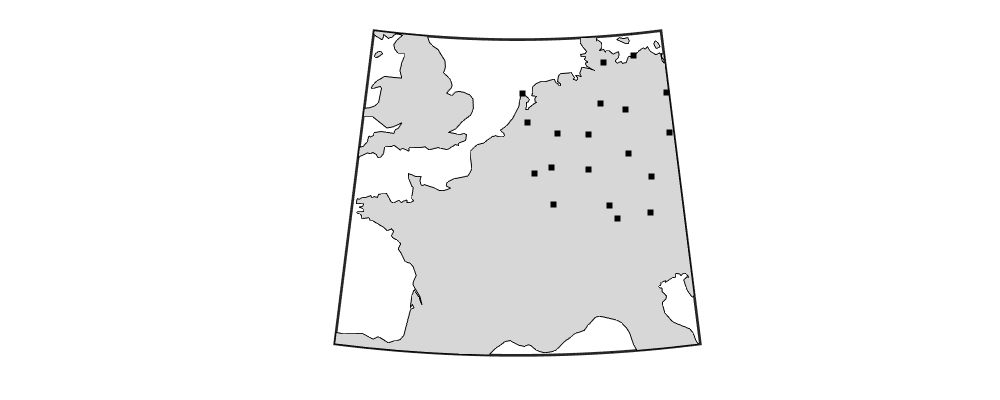

ang = mean(Mddm+[0 -pi]);
cc = [mean([dc.lat]),mean([dc.lon])];
ccl = repmat(cc,301,1)+(-10:0.1:20)'*[cos(ang) sin(ang)];
ccp = repmat(cc,301,1)+(-10:0.1:20)'*[cos(ang+pi/2) sin(ang+pi/2)];

figure('position',[0 0 1000 400]);
h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255);
%plotm(coastlat, coastlon,'k'); geoshow('worldrivers.shp','Color', 'blue')
scatterm([dc(id_no).lat],[dc(id_no).lon],'filled','k','s');

scatterm([dc(id_so).lat],[dc(id_so).lon],'filled','k','d');
scatterm(mean([dc.lat]),mean([dc.lon]),'filled','r');
textm([dc.lat]+0.6,[dc.lon],{dc.name},'HorizontalAlignment','center')

plotm(ccl,'-r')
plotm(ccp,'-g')

## Results

## **Overall trend**

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

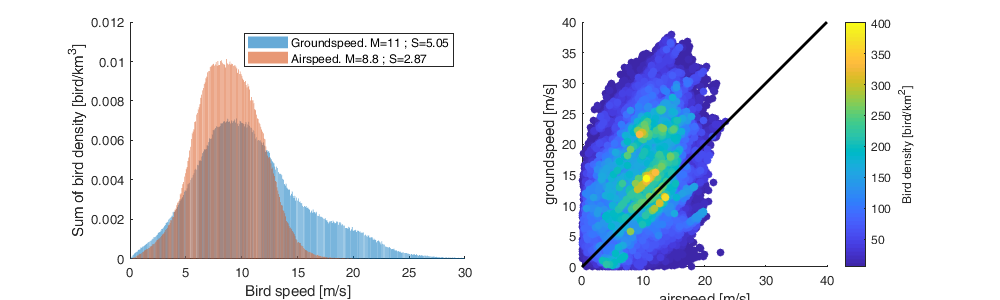

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g, dens);
bar(e,h,'FaceAlpha',0.6);
[e,h,Ma,Sa] = histvdens(v_a, dens);
bar(e,h,'FaceAlpha',0.6);
%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel('Bird speed [m/s]');
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(1,2,2); hold on;
[~, id] = sort(dens(:)); id2 = id(dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(v_a(id2),v_g(id2),[],dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2)
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; c.Label.String='Bird density [bird/km^2]';

Histograms of airspeed and ground speed are normalized by the density of bird, that is, each bin of bird speed is multiply not by the number of occuruance in the dataset but by the sum of all bird density flying at this speed. 

(a) Bird move at around 11 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.7m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

**Difference in Season**

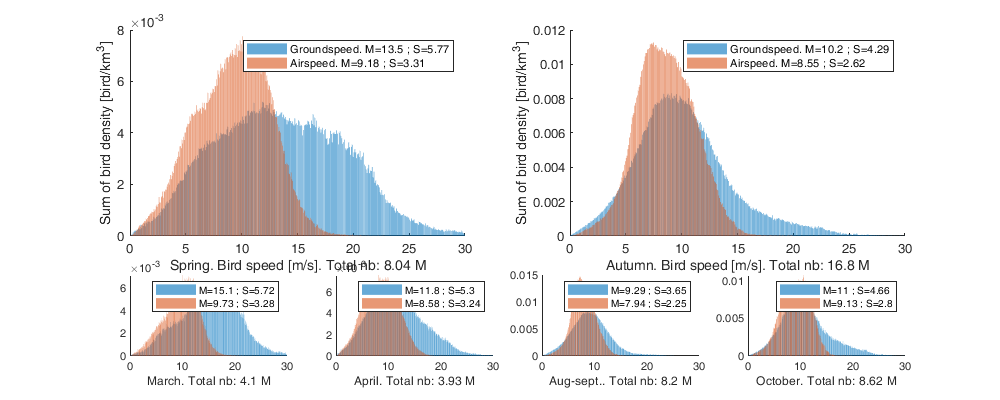

figure('position',[0 0 1000 400]);

subplot(3,2,[1 3]); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,:),dens(id_sp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,:),dens(id_sp,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Spring. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(3,2,[2 4]); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,:),dens(id_au,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,:),dens(id_au,:,:));
bar(e,h,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
legend; xlabel(['Autumn. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

for i_s=1:size(id_s,1)
    subplot(3,4,8+i_s); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
    bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
    [e,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
    bar(e,h,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
    legend; xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,:))))/1000000,3) ' M']);xlim([0 30]);
end

While the bird are moving with quite different ground speed (blue) regime in Spring (left) and Autumn (right), their actual airspeed (red) is impresively similar. Note that the total number of bird measured is very different in spring (7.88M bird/km3) and autumn (19.8M bird/km3). This is because spring is shorter, thus less measurement and it doesn't represent the actual number of bird flying through. 

## Geographical variation

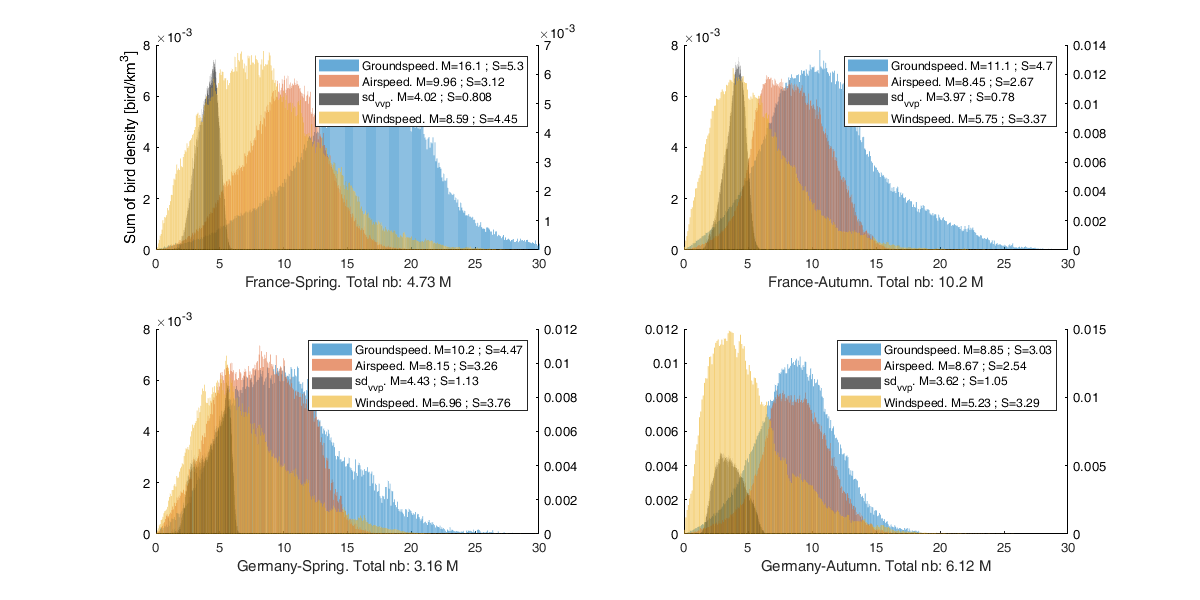

figure('position',[0 0 1200 600]);

subplot(2,2,1); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_fr),dens(id_sp,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_fr),dens(id_sp,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_fr),dens(id_sp,:,id_fr));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
legend; xlabel(['France-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_fr),3)))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(2,2,2); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_fr),dens(id_au,:,id_fr));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_fr),dens(id_au,:,id_fr));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_fr),dens(id_au,:,id_fr));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['France-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_fr),3)))/1000000,3) ' M']);

subplot(2,2,3); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_sp,:,id_de),dens(id_sp,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_sp,:,id_de),dens(id_sp,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_de),dens(id_sp,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['Germany-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_de),3)))/1000000,3) ' M']);

subplot(2,2,4); hold on;
[e,h,Mg,Sg] = histvdens(v_g(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[e,h,Ma,Sa] = histvdens(v_a(id_au,:,id_de),dens(id_au,:,id_de));
bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[e,h,Mw,Sw] = histvdens(v_w(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis right; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
[e,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_de),dens(id_au,:,id_de));
yyaxis left; bar(e,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; xlim([0 30])
xlabel(['Germany-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_de),3)))/1000000,3) ' M']);  legend

In this figure, we seperate both in term of region: France (top) and Germany (bottom) and Season: Spring (left) and Autumn (right). We also added the windspeed in yellow to help explain the difference between France and Germany.

Groundspeed is suprinsigly much higher in the radar in France, particularly in Spring (15.7 m/s vs 9.5 for Germany). However, airspeed is much more similar between France and Germany (9m/s vs 8.5 m/s for Germany). This difference in groundspeed uniquely is well explained by the windspeed (yellow). Indeed, in France birds benefit from a better wind speed (6m/s vs 5m/s germany) allowing them to increase their groundspeed. 

Note that this windspeed is the norm of the vector and not a projection on the prefered direction of migration. However, it is normalized by the number of bird in the air, thus the windspeed is representative of the wind support of bird migration. 

Is this a pattern unique to 2018?

More figures are plotted in Supplementary material down the page. 

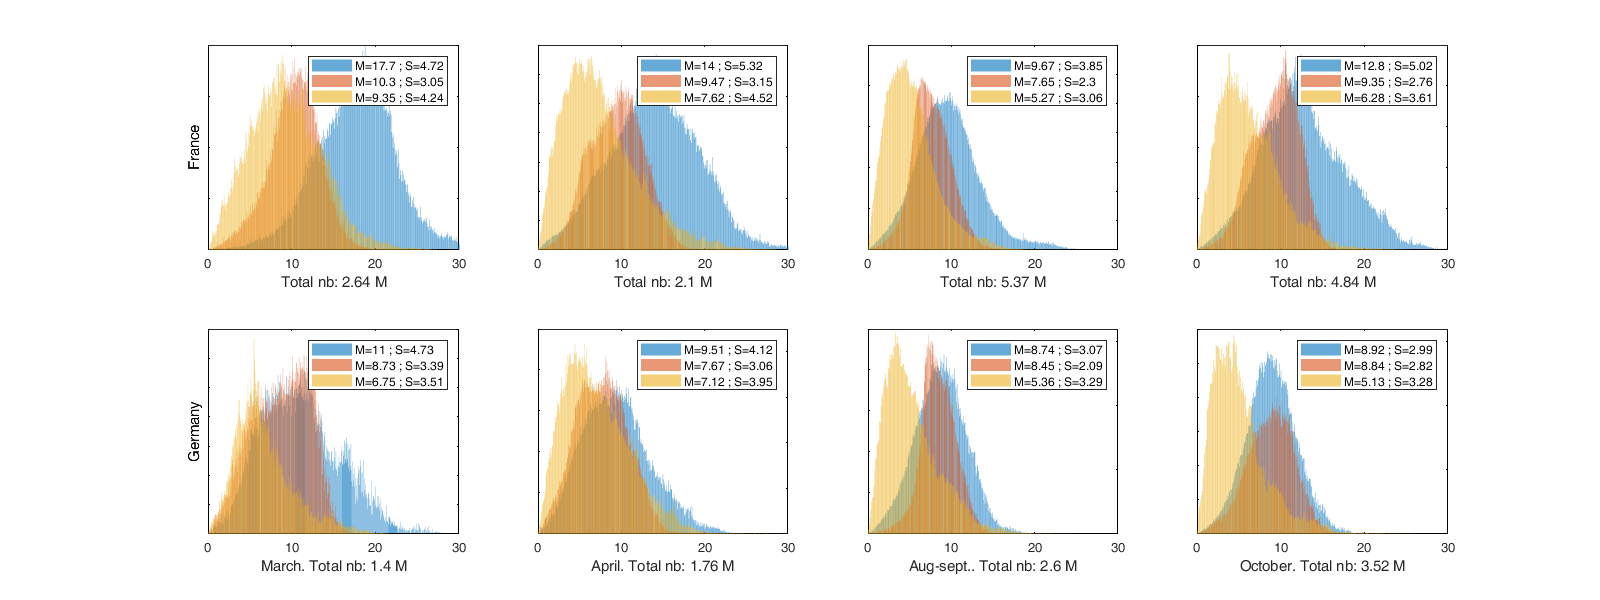

figure('position',[0 0 1600 600]);

for i_s=1:size(id_s,1)
    subplot(2,4,i_s); hold on;
    [e,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    bar(e,h,'FaceAlpha',0.6);
    if i_s==1, ylabel('France'), end
    [e,h,Mw,Sw] = histvdens(v_w(id_s(i_s,:),:,id_fr),dens(id_s(i_s,:),:,id_fr));
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_fr),3)))/1000000,3) ' M']);xlim([0 30]); box on;

    subplot(2,4,i_s+4); hold on;
    [e,h,Mg,Sg] = histvdens(v_g(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Mw,Sw] = histvdens(v_w(id_s(i_s,:),:,id_de),dens(id_s(i_s,:),:,id_de));
    if i_s==1, ylabel('Germany'), end
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(e,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_de),3)))/1000000,3) ' M']);xlim([0 30]); box on;
end


Mg=nan(numel(dc),size(id_s,1)); Mgw=Mg; gu=Mg; gv=Mg; gwu=Mg; gwv=Mg; awu=Mg; awv=Mg; wwu=Mg; wwv=Mg; Maw=Mg; Mww=Mg;
for i_d = 1:numel(dc)
    for i_s = 1:size(id_s,1)
        Md(i_d,i_s) = nanmean(reshape(dens(id_s(i_s,:),:,i_d),1,[]));
        Mg(i_d,i_s) = nanmean(reshape(v_g(id_s(i_s,:),:,i_d),1,[]));
        gu(i_d,i_s) = nanmean(reshape(dc(i_d).u2(id_s(i_s,:),:),1,[]));
        gv(i_d,i_s) = nanmean(reshape(dc(i_d).v2(id_s(i_s,:),:),1,[]));
        Mw(i_d,i_s) = nanmean(reshape(v_w(id_s(i_s,:),:,i_d),1,[]));
        wu(i_d,i_s) = nanmean(reshape(dc(i_d).windu(id_s(i_s,:),:),1,[]));
        wv(i_d,i_s) = nanmean(reshape(dc(i_d).windv(id_s(i_s,:),:),1,[]));
        [~,~,Mgw(i_d,i_s)] = histvdens(v_g(id_s(i_s,:),:,i_d),dens(id_s(i_s,:),:,i_d));
        [~,~,gwu(i_d,i_s)] = histvdens(dc(i_d).u2(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
        [~,~,gwv(i_d,i_s)] = histvdens(dc(i_d).v2(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
        [~,~,Maw(i_d,i_s)] = histvdens(v_a(id_s(i_s,:),:,i_d),dens(id_s(i_s,:),:,i_d));
        [~,~,awu(i_d,i_s)] = histvdens(dc(i_d).ua(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
        [~,~,awv(i_d,i_s)] = histvdens(dc(i_d).va(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
        [~,~,Mww(i_d,i_s)] = histvdens(v_w(id_s(i_s,:),:,i_d),dens(id_s(i_s,:),:,i_d));
        [~,~,wwu(i_d,i_s)] = histvdens(dc(i_d).windu(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
        [~,~,wwv(i_d,i_s)] = histvdens(dc(i_d).windv(id_s(i_s,:),:),dens(id_s(i_s,:),:,i_d));
    end
end


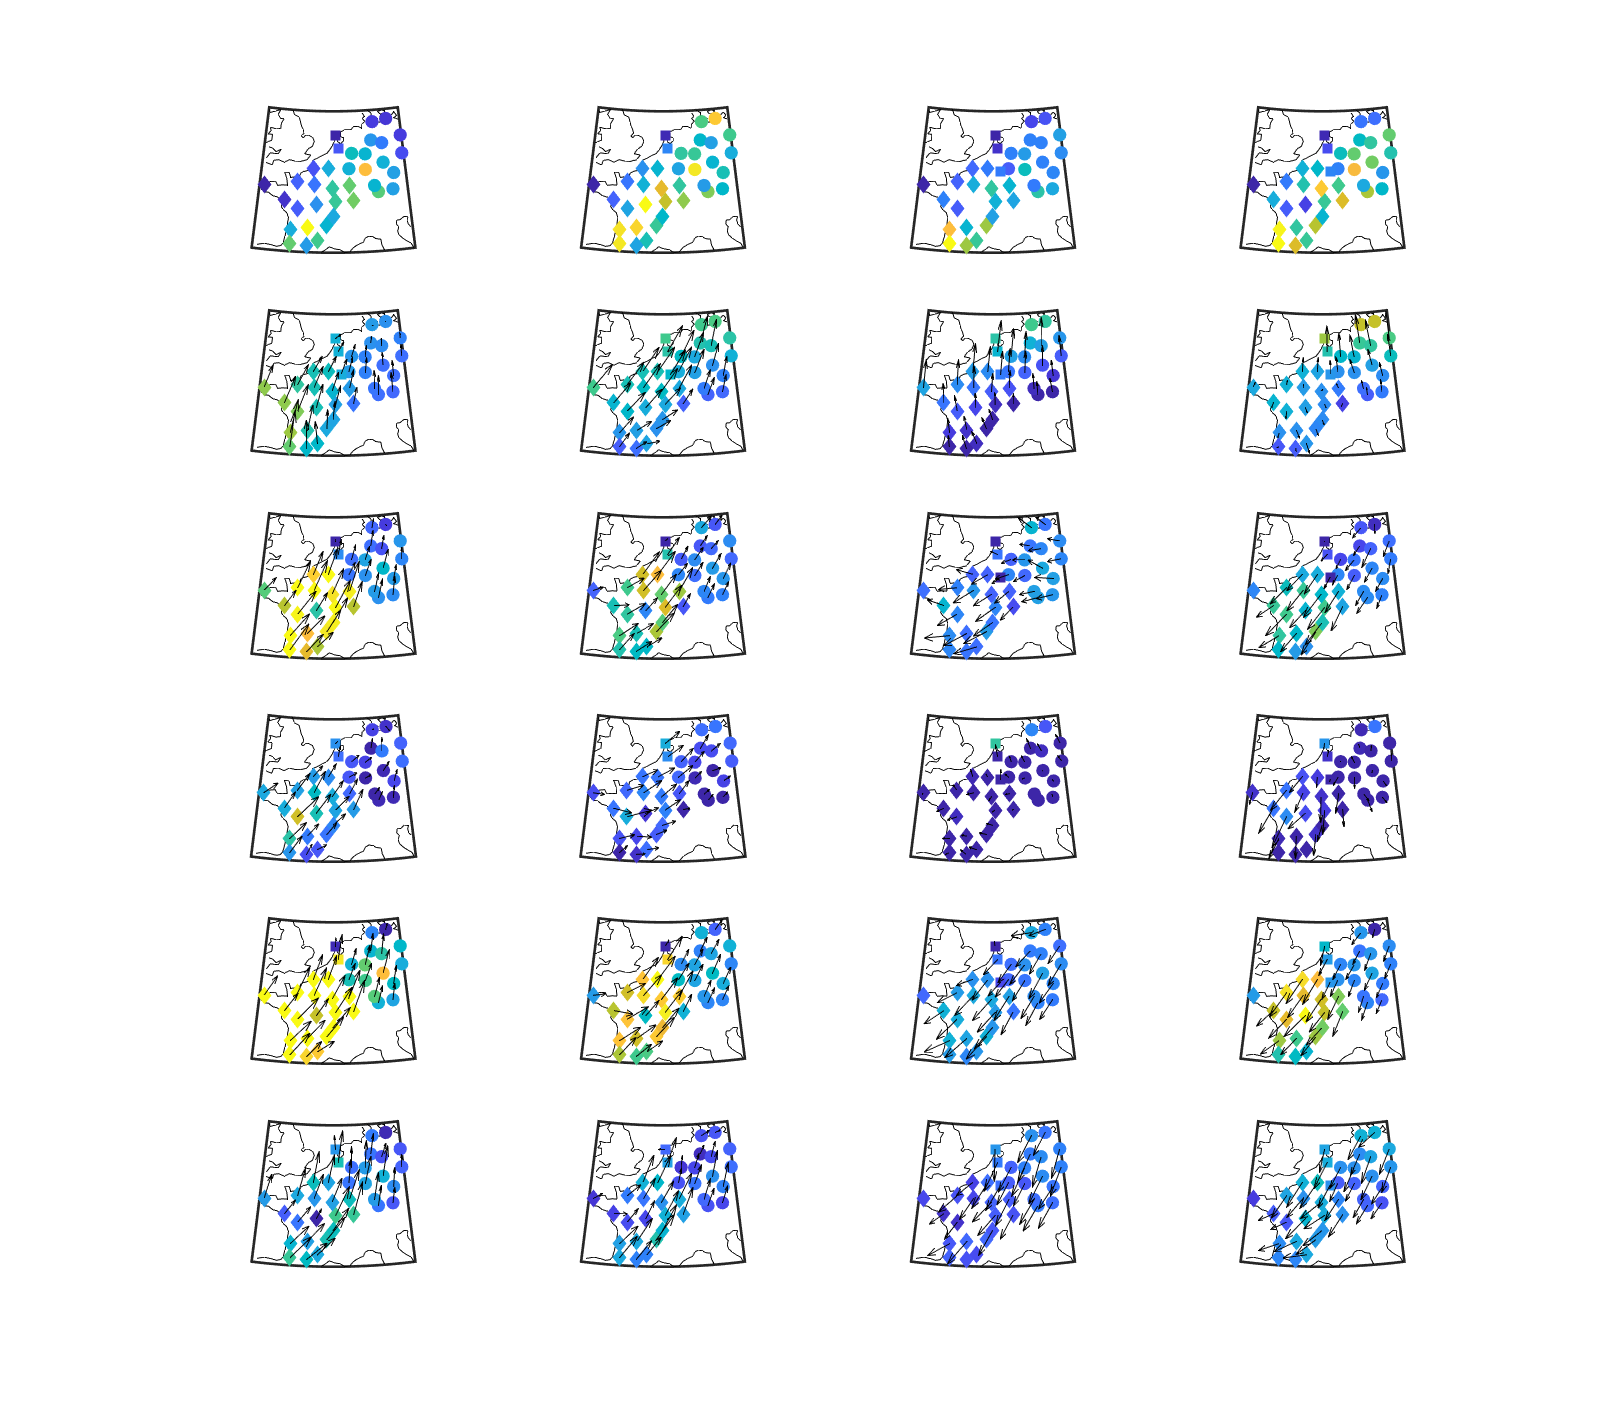

figure('position',[0 0 1600 2400]); 
for i_s = 1:size(id_s,1)
    subplot(6,4,i_s); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Md(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Md(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Md(id_fr,i_s),'d','filled');  
    if i_s==1, ylabel('Density 1-5 bird/km^2'); end

    subplot(6,4,i_s+4); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mw(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wu(:,i_s),wv(:,i_s),'k')
    caxis([6 16]) 
    if i_s==1, ylabel('All windspeed'); end
    
    subplot(6,4,i_s+8); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mg(id_de,i_s),'filled'); 
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mg(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mg(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',gu(:,i_s),gv(:,i_s),'k')
    caxis([6 16]) 
    if i_s==1, ylabel('All groundspeed'); end
    
    subplot(6,4,i_s+12); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mww(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mww(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mww(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',wwu(:,i_s),wwv(:,i_s),'k')
    caxis([6 16])
    if i_s==1, ylabel('Weighted windspeed'); end
    
    subplot(6,4,i_s+16); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Mgw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Mgw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Mgw(id_fr,i_s),'d','filled'); 
    quiverm([dc.lat]',[dc.lon]',gwu(:,i_s),gwv(:,i_s),'k')
    caxis([6 16]) 
    
    subplot(6,4,i_s+20); hold on; 
    h=worldmap([floor(min([dc.lat])) ceil(max([dc.lat]))], [floor(min([dc.lon])) ceil(max([dc.lon]))]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
    scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,Maw(id_de,i_s),'filled');
    scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,Maw(~id_de&~id_fr,i_s),'s','filled');
    scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,Maw(id_fr,i_s),'d','filled');
    quiverm([dc.lat]',[dc.lon]',awu(:,i_s),awv(:,i_s),'k')
    caxis([6 16])
    if i_s==1, ylabel('Weighted airspeed'); end
    ylabel(id_s_name{i_s})
end

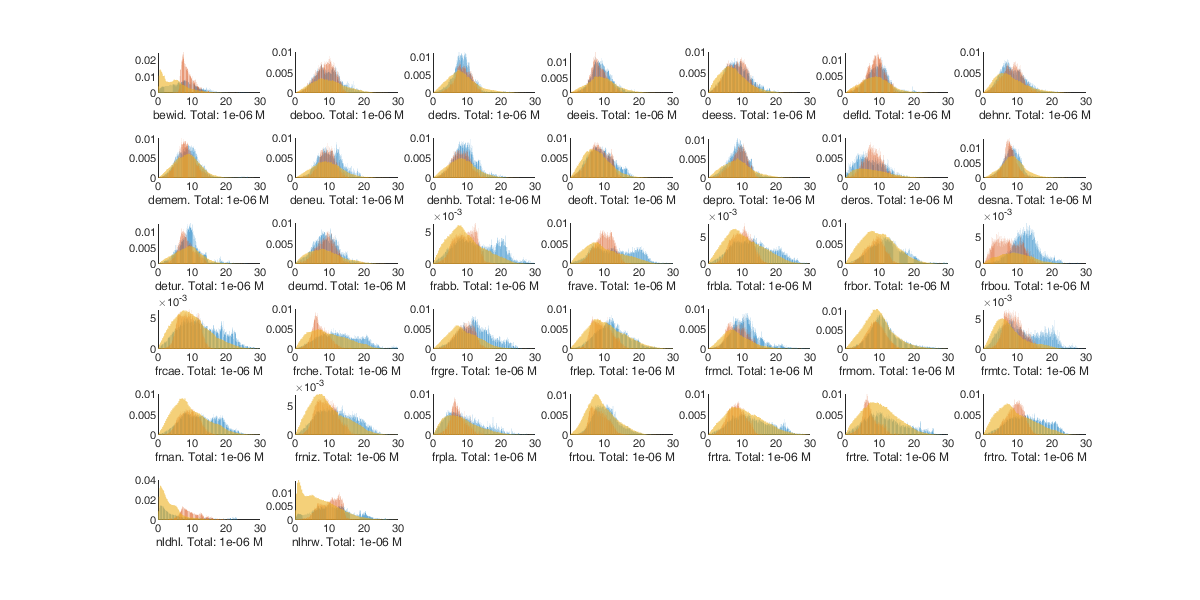

figure('position',[0 0 1200 600]);
Mg=nan(1,numel(dc));Sg=Mg;Ma=Mg;Sa=Mg;Mw=Mg;Sw=Mg;
for i_d= 1:numel(dc)
    subplot(6,7,i_d); hold on
    [e,h,Mg(i_d), Sg(i_d)] = histvdens(v_g(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma(i_d), Sa(i_d)] = histvdens(v_a(:,:,i_d),dens(:,:,i_d));
    bar(e,h,'FaceAlpha',0.6);
    histogram(v_g(:,:,i_d),'Normalization', 'pdf','FaceAlpha',0.6,'EdgeAlpha',0)
    %[e,h,Mw(i_d), Sw(i_d)] = histvdens(v_w(:,:,i_d),dens(:,:,i_d));
    %bar(e,h,'FaceAlpha',0.6);
    % legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ dc(i_d).name '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]);
end

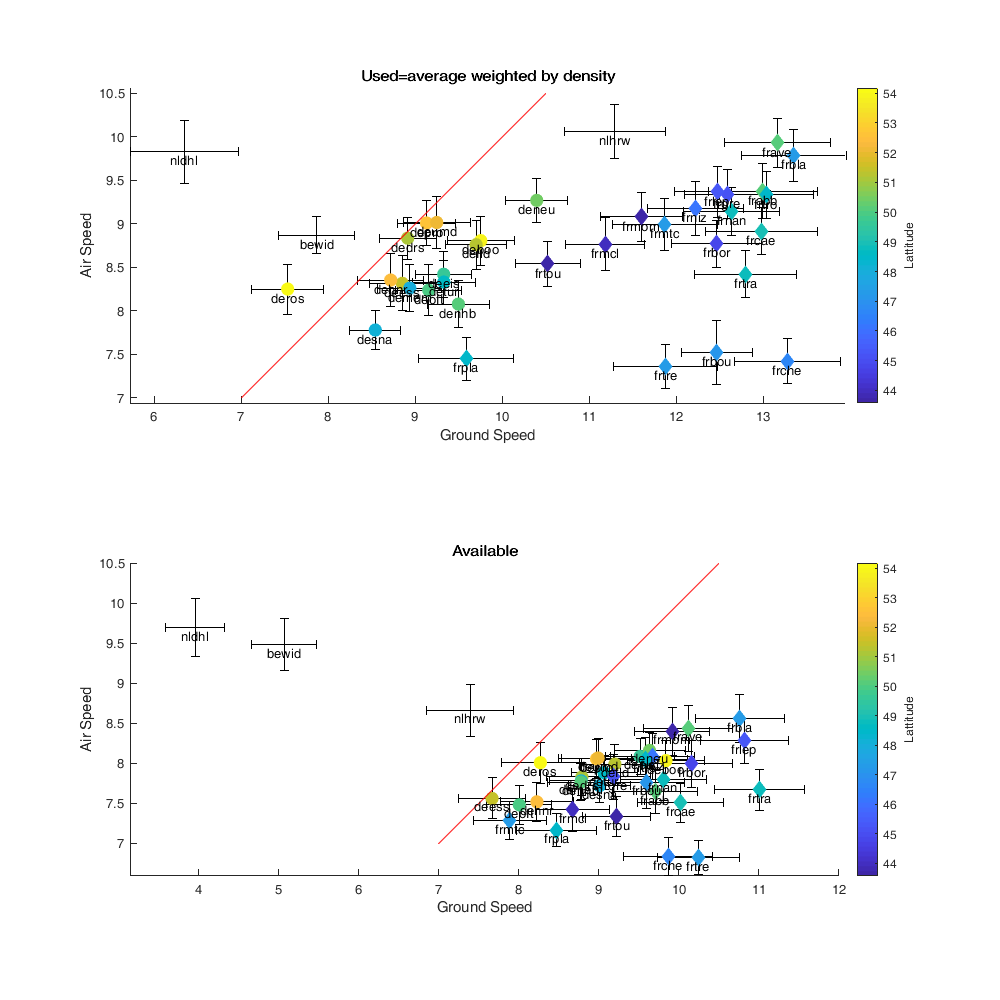

figure('position',[0 0 1000 1000]); 
subplot(2,1,1);hold on;
eb(1) = errorbar(Mg,Ma,Sg/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg,Ma,Sa/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg(id_de),Ma(id_de),100,[dc(id_de).lat],'filled');
scatter(Mg(~id_de&~id_fr),Ma(~id_de&~id_fr),100,[dc(~id_de&~id_fr).lat],'s','filled');
scatter(Mg(id_fr),Ma(id_fr),100,[dc(id_fr).lat],'d','filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg,Ma-0.1,{dc.name},'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude';
title('Used=average weighted by density')
subplot(2,1,2); hold on;
Mg2=nanmean(reshape(v_g,[],numel(dc)));
Ma2=nanmean(reshape(v_a,[],numel(dc)));
Sg2=nanstd(reshape(v_g,[],numel(dc)));
Sa2=nanstd(reshape(v_a,[],numel(dc)));
eb(1) = errorbar(Mg2,Ma2,Sg2/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg2,Ma2,Sa2/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg2(id_de),Ma2(id_de),100,[dc(id_de).lat],'filled');
scatter(Mg2(~id_de&~id_fr),Ma2(~id_de&~id_fr),100,[dc(~id_de&~id_fr).lat],'s','filled');
scatter(Mg2(id_fr),Ma2(id_fr),100,[dc(id_fr).lat],'d','filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg2,Ma2-0.1,{dc.name},'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude'; title('Available')

There is a very strong difference visible at the country level. In Germany, the difference between airspeed and ground speed is very small while in French, the pattern observed earlier is most consistant.

## **Variation with Altitude**

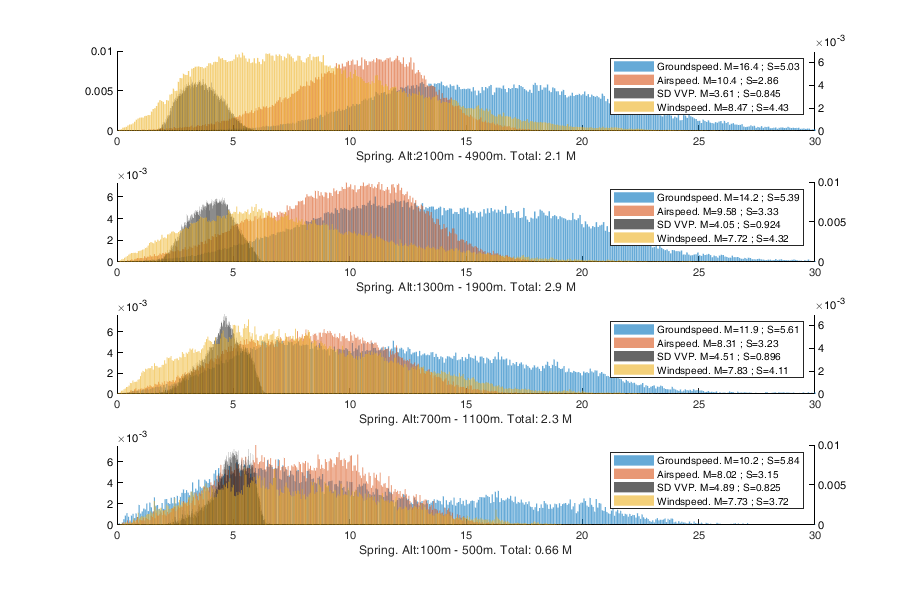

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_sp,id_a,:),dens(id_sp,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Mw,Sw] = histvdens(v_w(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis right; bar(e,h,'FaceAlpha',0.6);
    [e,h, Ms, Ss ] = histvdens(sd_vvp(id_sp,id_a,:),dens(id_sp,id_a,:));
    yyaxis left; bar(e,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Spring. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_sp,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

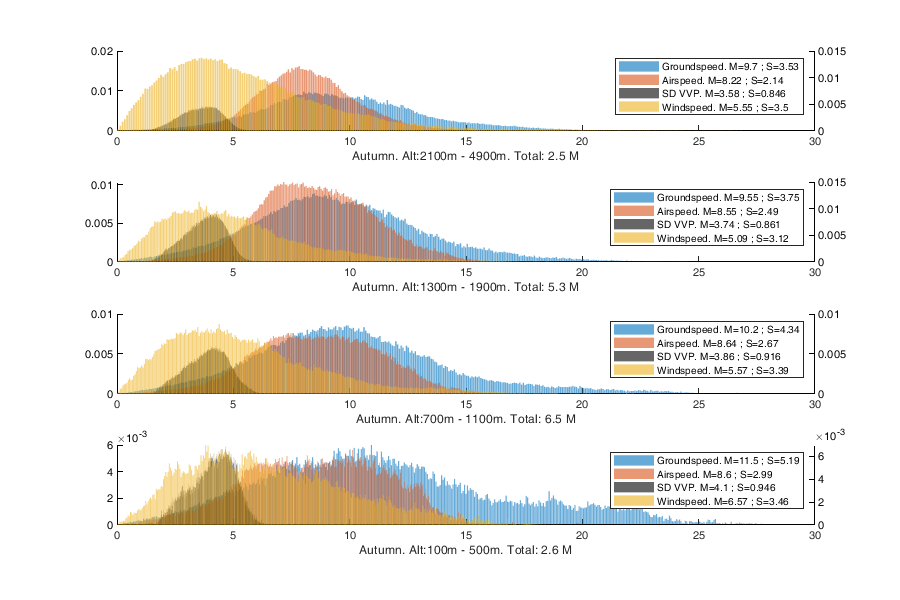

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
 for i_a= 1:numel(a)-1
    id_a = dc(1).alt>a(i_a) & dc(1).alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [e,h,Mg,Sg] = histvdens(v_g(id_au,id_a,:),dens(id_au,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Ma,Sa] = histvdens(v_a(id_au,id_a,:),dens(id_au,id_a,:));
    bar(e,h,'FaceAlpha',0.6);
    [e,h,Mw,Sw] = histvdens(v_w(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis right; bar(e,h,'FaceAlpha',0.6);
    [e,h, Ms, Ss] = histvdens(sd_vvp(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis left; bar(e,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Autumn. Alt:' num2str(min(dc(1).alt(id_a))) 'm - ' num2str(max(dc(1).alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_au,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

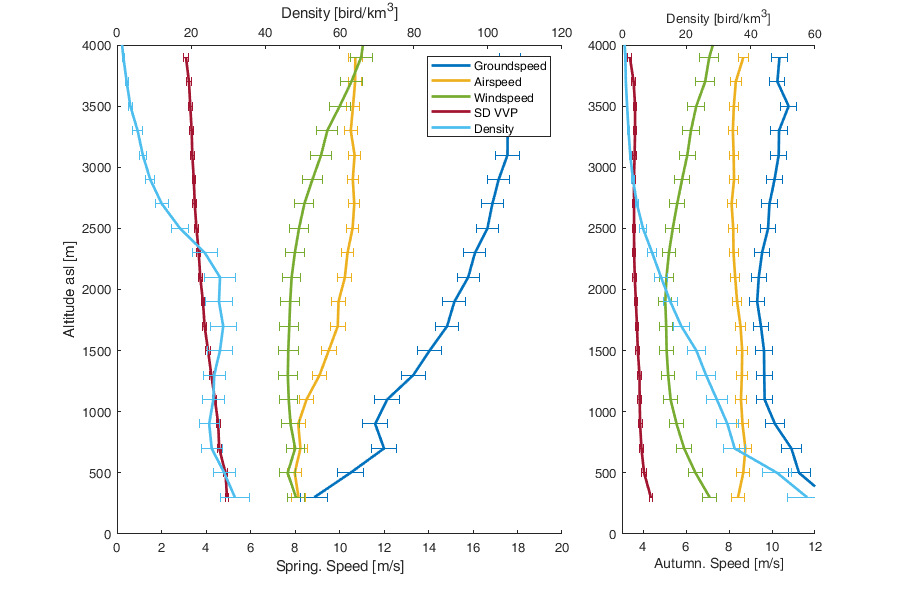

Mg = nan(numel(dc(1).alt),2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_sp,i_a,:),dens(id_sp,i_a,:));
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_au,i_a,:),dens(id_au,i_a,:));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_au,i_a,:),dens(id_au,i_a,:));
end

figure('position',[0 0 900 600]);
subplot(1,3,[1 2]); hold on;
tmp = errorbar(Mg(:,1),dc(1).alt,Sg(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,1),dc(1).alt,Sa(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,1),dc(1).alt,Sw(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,1),dc(1).alt,Ss(:,1)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
xlim([0 20]);ylabel('Altitude asl [m]'); xlabel('Spring. Speed [m/s]'); ylim([0 4000]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,1),dc(1).alt,Sd(:,1)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,1),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 120]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(1,3,3); hold on;
tmp = errorbar(Mg(:,2),dc(1).alt,Sg(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ma(:,2),dc(1).alt,Sa(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,2),dc(1).alt,Sw(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,2),dc(1).alt,Ss(:,2)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([3 12]); xlabel('Autumn. Speed [m/s]'); ylim([0 4000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(Md(:,2),dc(1).alt,Sd(:,2)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,2),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
xlabel('Density [bird/km^3]'); ylim([0 4000]); xlim([0 60])

Thick line represent the mean and the error bird the 1 standard deviation computed at each altitude bin and weighted by the density of bird. `sd_vvp` is the variance of groundspeed within the bin. The size of the Spring and Autumn subplot are scaled to have the same axis scale. 

Ground speed generally increase with altitude, but airspeed increase much less as windspeed explain in great part the increase of groundspeed. This effect is visible in both spring and autumn. The profile of groundspeed and windspeed matches well in both season, making the airspeed profile relatively straight (at least in comparison to windspeed and groundspeed). 

The decrease of `sd_vvp` with altitude indicates a more directional flow of bird in high altitude (less variance in groundspeed). This variability is certainly explained by bird flying in more diverse direction at low elevation and consequently reducing the average ground speed (and airspeed!) of the bin as measure by weather radar. One could try to argue that the "angle" (derivative with regard to altitude) in sd_vvp and airspeed are matching (e.g. 100-500m bin in autumn).

## **Progress of night**

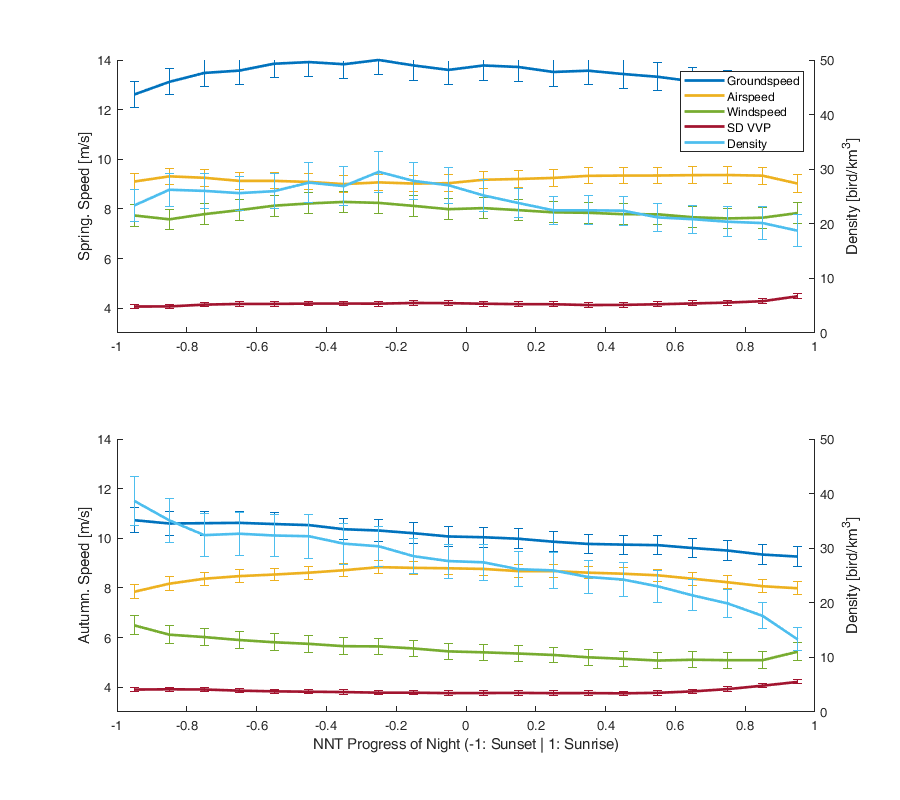

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_sp',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_a),dens(id_a));
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_au',1,numel(dc)),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(v_g(id_a),dens(id_a));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(v_a(id_a),dens(id_a));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_a),dens(id_a));
end

figure('position',[0 0 900 800]);
subplot(2,1,1); hold on;
tmp = errorbar(mida, Mg(:,1),Sg(:,1)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,1),Sa(:,1)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,1),Sw(:,1)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,1),Ss(:,1)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,1),'-','Color',tmp.Color,'LineWidth',2); 
ylim([3 14]);ylabel('Altitude asl [m]'); ylabel('Spring. Speed [m/s]'); xlim([-1 1]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,1),Sd(:,1)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,1),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});

subplot(2,1,2); hold on;
tmp = errorbar(mida, Mg(:,2),Sg(:,2)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ma(:,2),Sa(:,2)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,2),Sw(:,2)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,2),Ss(:,2)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,2),'-','Color',tmp.Color,'LineWidth',2);
ylim([3 14]); ylabel('Autumn. Speed [m/s]'); xlim([-1 1]); xlabel('NNT Progress of Night (-1: Sunset | 1: Sunrise)');
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,2),Sd(:,2)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,2),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
ylabel('Density [bird/km^3]'); xlim([-1 1]); ylim([0 50]); 

We use the NNT which normalize the time between sunset and sunrise between -1 and 1. Both Windspeed and Groundspeed slightly increase in the first hours of the night in Spring maintining the airspeed at a relative constant speed. In autumn, there seems to be an increase of airspeed in thos same hours because groundspeed remains constant while windspeed reduces slightly. The sd_vvp seems to remains relatively constant throughout the night although increase early morning probably due to the start of diunarl movement contamination. 

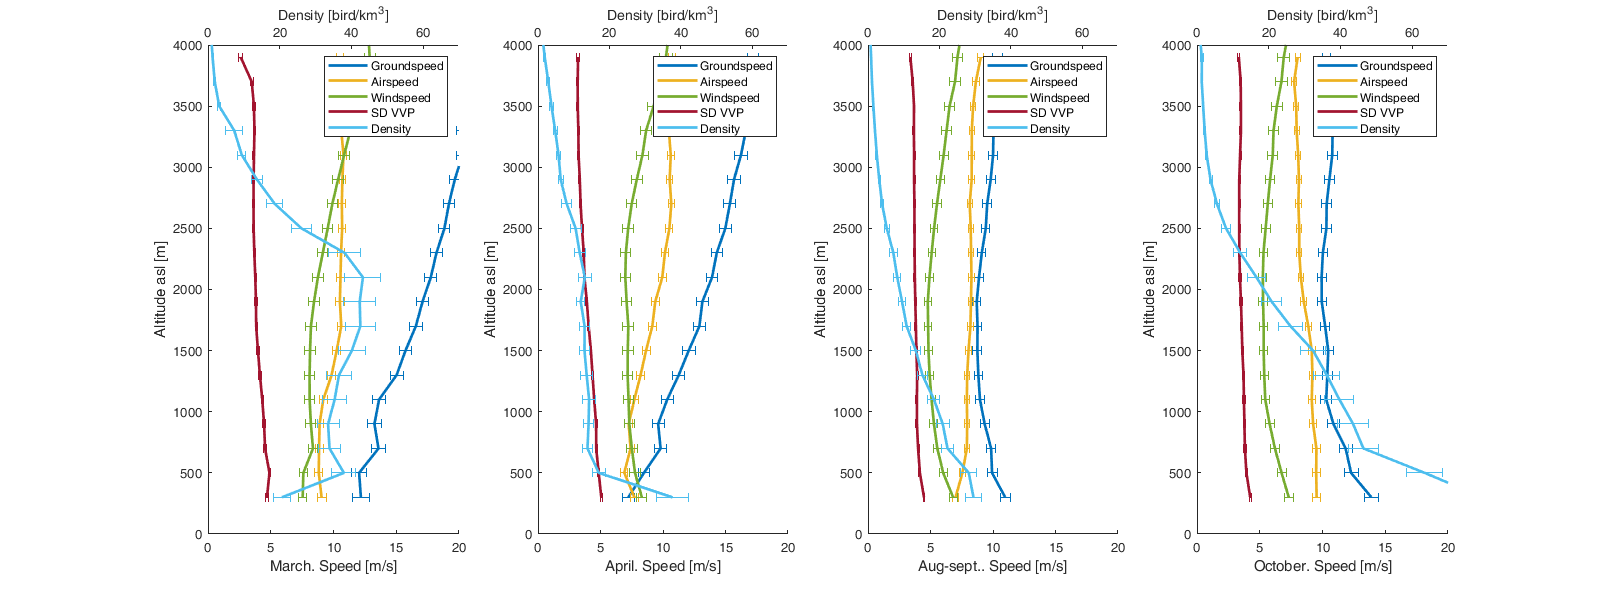

Mg = nan(numel(dc(1).alt),4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc(1).alt)
    for i_s=1:size(id_s)
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(v_g(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(v_a(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_w(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
    end
end

figure('position',[0 0 1600 600]);
for i_s=1:size(id_s)
    subplot(1,4,i_s); hold on;
    tmp = errorbar(Mg(:,i_s),dc(i_s).alt,Sg(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(1)=plot(Mg(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Ma(:,i_s),dc(i_s).alt,Sa(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(2)=plot(Ma(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Mw(:,i_s),dc(i_s).alt,Sw(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(3)=plot(Mw(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Ms(:,i_s),dc(i_s).alt,Ss(:,i_s)/10, 'horizontal', 'LineStyle', 'none'); l(4)=plot(Ms(:,i_s),dc(i_s).alt,'-','Color',tmp.Color,'LineWidth',2); 
    xlim([0 20]);ylabel('Altitude asl [m]'); xlabel([id_s_name{i_s} '. Speed [m/s]']); ylim([0 4000]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; c = get(gca,'colororder'); 
    tmp = errorbar(Md(:,i_s),dc(1).alt,Sd(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(Md(:,i_s),dc(1).alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
    xlabel('Density [bird/km^3]'); ylim([0 4000]);  xlim([0 70]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});
end

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    for i_s=1:size(id_s)
        id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_s(i_s,:)',1,numel(dc)),[1 3 2]),1,25,1);
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(v_g(id_a),dens(id_a));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(v_a(id_a),dens(id_a));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_w(id_a),dens(id_a));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_a),dens(id_a));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_a),dens(id_a));
    end
end

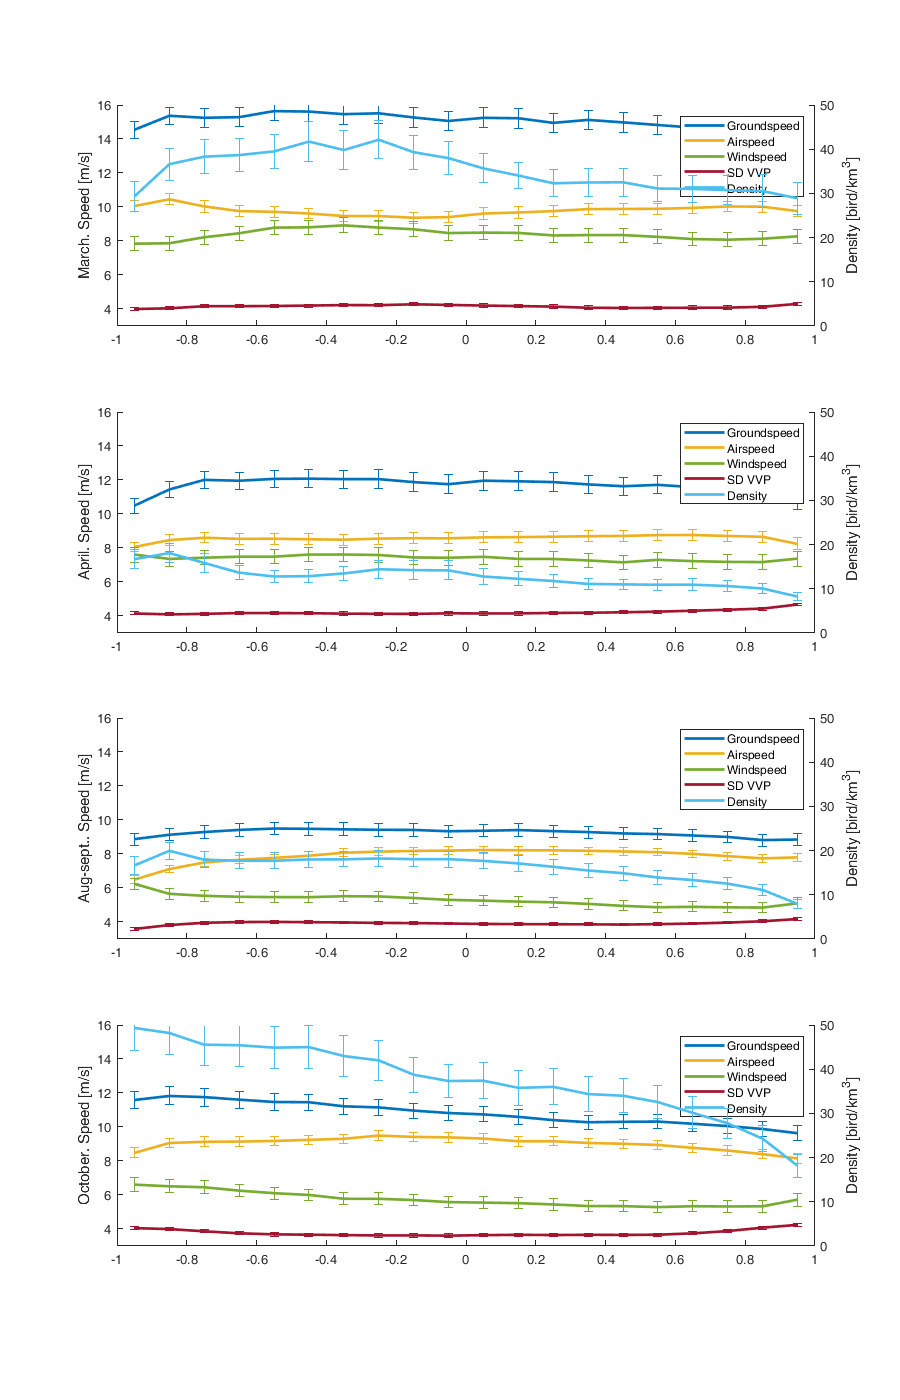

figure('position',[0 0 900 1400]);
for i_s=1:size(id_s)
    subplot(4,1,i_s); hold on;
    tmp = errorbar(mida, Mg(:,i_s),Sg(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(1)=plot(mida, Mg(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Ma(:,i_s),Sa(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(2)=plot(mida, Ma(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Mw(:,i_s),Sw(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(3)=plot(mida, Mw(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Ms(:,i_s),Ss(:,i_s)/10, 'vertical', 'LineStyle', 'none'); l(4)=plot(mida, Ms(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    ylim([3 16]);ylabel('Altitude asl [m]'); ylabel([id_s_name{i_s} '. Speed [m/s]']); xlim([-1 1]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
    tmp = errorbar(mida, Md(:,i_s),Sd(:,i_s)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',c(6,:)); l(5)=plot(mida, Md(:,i_s),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',c(6,:)); 
    ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'});
end

**Local Functions**

function [e,h,M,S] = histvdens(a,b,bin,norm)
    if ~exist('bin','var'), bin = 500; end
    if ~exist('norm','var'), norm = true; end
    id = ~isnan(a(:))&~isnan(b(:));
    if sum(id(:))==0
        e=nan;
        h=nan;
        M=nan;
        S=nan;        
    else
        [Y,edge] = discretize(a(id),bin,'IncludedEdge','right'); 
        [G,ID] = findgroups(Y);
        h=zeros(numel(edge)-1,1);
        h(ID) = splitapply(@sum, b(id), G);    
        e = 0.5 * (edge(1:end-1) + edge(2:end));
        M = a(id)'*b(id)/nansum(b(id));
        S = nanstd(a(id),b(id));%S = nanstd(v(id & dens>0),dens(id & dens>0));
        if norm, h=h./nansum(h); end
    end
end